`select 20 images randomly for classification`

idx = randperm(numel(imdsValidation.Files),20);
[YPred,scores] = classify(netTransfer,augimdsValidation);

`display the results`

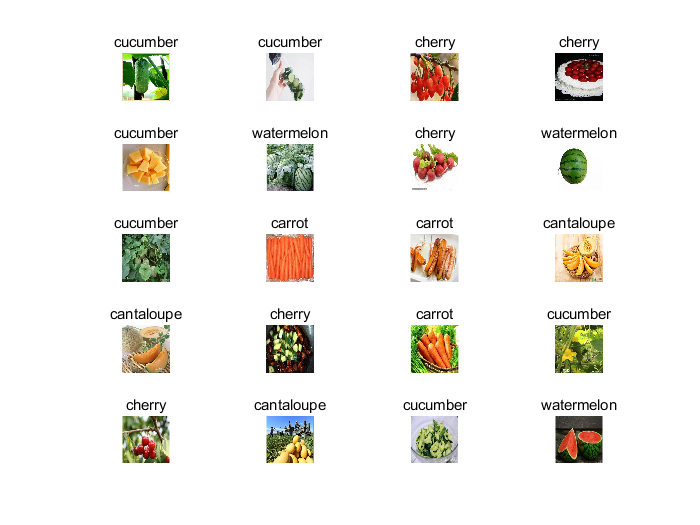

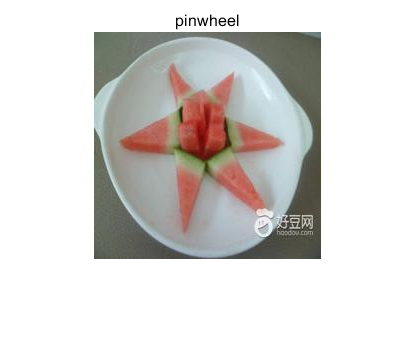

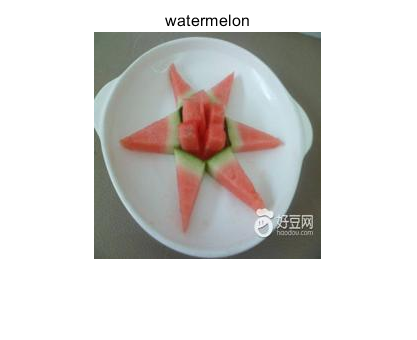

figure
for i = 1:20
    subplot(5,4,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

`Use the network before and after training to classify a identical picture`

I = imread('D:\workspace\MATLAB\DAN2019\images\watermelon\1c06ca40-cbb0-11e9-b7b7-2a3a4d15adc9.jpg');
I = imresize(I,inputSize(1:2));
label1 = classify(net,I);
label2 = classify(netTransfer,I);
figure('numbertitle','off','name','net','color','white')
imshow(I)
title(label1)
figure('numbertitle','off','name','netTransfer','color','white')
imshow(I)
title(label2)